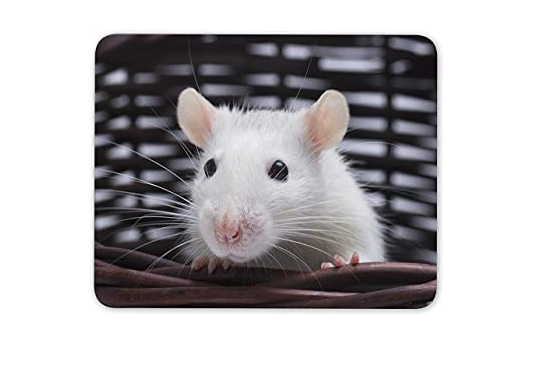

clc; clear; close all

img=imread('Test_rat_image.jpg');
imshow(img)

I=rgb2gray(img);

%I_sobel=edge(I,'Sobel');
[I, threshold]=edge(I,'sobel');

Threshold

threshold

threshold = 0.1573

[I_edge, threshold]=edge(I,'sobel',2.5*threshold);
% [I_canny2, threshold]=edge(I,'Canny',.5*threshold);


Eye isolation

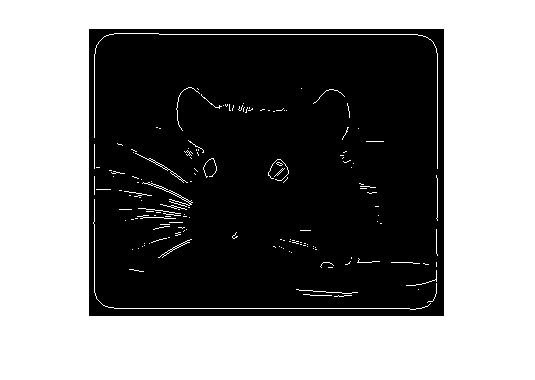

se90=strel('line',3,90);
se0=strel('line',3,0);
I_dilate=imdilate(I_edge,[se90 se0]);

I_fill=imfill(I_dilate,'holes');
 I_erode=imerode(I_fill,[se90 se0]);
I_erode=imerode(I_erode,[se90 se0]);
I_clear=imclearborder(I_erode);

imshow(I)

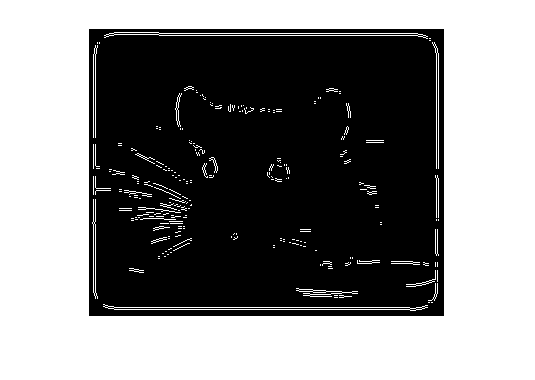

imshow(I_edge)

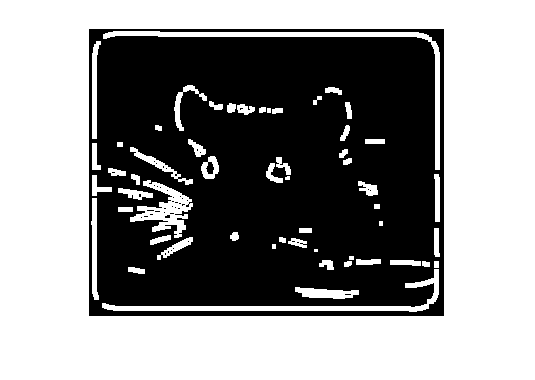

imshow(I_dilate)

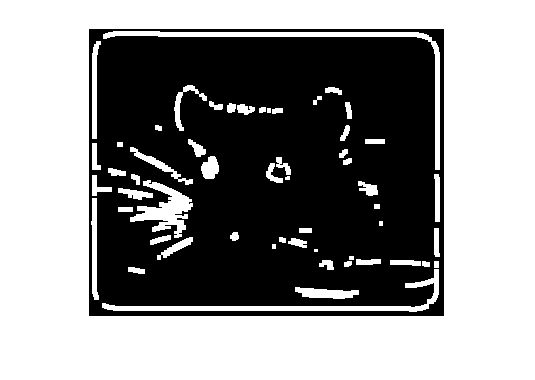

imshow(I_fill)

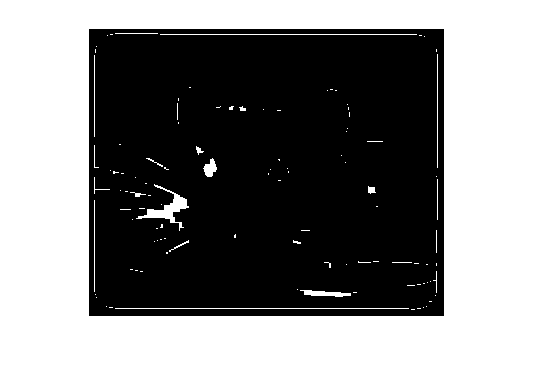

imshow(I_erode)

imshow(I_clear)